# 大滞后过程采样控制仿真

被控对象传递函数：$G_s=\frac{K}{T\cdot s +1} e^{-\tau_0 s$，$K=10,T=5,\tau_0=2$，请在同一个plot图中绘制采样周期（采样控制间隔）$T_s=0.1,1,1.5,2.5$四种情况下的闭环采样控制响应曲线

K=10;
T=6;
tau0=2;
s=tf('s');
Ts_list=[1.5,1.8,2.2,2.5];
Gs=K/(T*s+1)*exp(-tau0*s)


Gs =
 
                10
  exp(-2*s) * -------
              6 s + 1
 
Continuous-time transfer function.



## 采样控制效果

figure();
hold on;
for Ts=Ts_list
    Gz=c2d(Gs,Ts,'zoh');
    Gc=pidtune(Gz,'PI');
    Phi=feedback(series(Gc,Gz),1);
    Phi.Name="Ts="+Ts;
    stepplot(Phi);
end

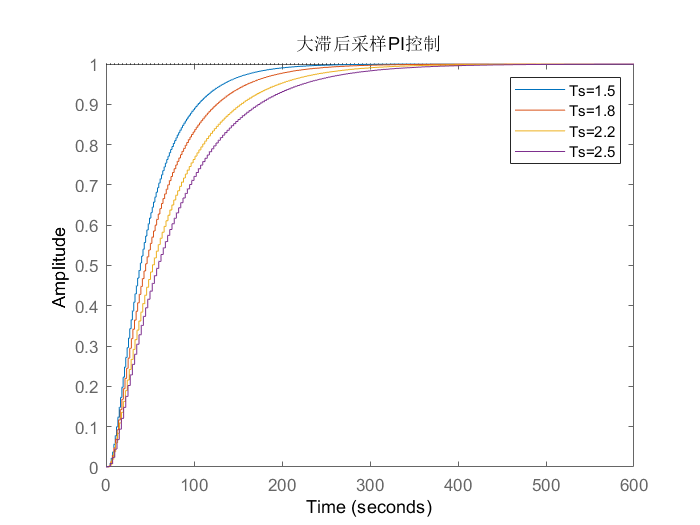

legend;hold off;
title("大滞后采样PI控制")